% todo:
% - get actual hydro coeffs (check)
% - loop to get coeffs as a function of frequency
% - get excitation force
% - update auto BCs to work with different N,M,K
% - find the difference between auto BCs and regular BCs
% - h = 1 gives divide by zero error, investigate
% - write symbolic to file so it runs the solve fast
% - do convergence study on hydro coeff and matching quality vs N
% - check that the same dimensions scaled by some constant give the same
% nondim hydro coeffs

% extensions for later:
% - try the more convenient i2 eigenfunctions mentioned in the 2012 paper
% - condense the A-matrix to be 2M x 2M from p7 of notebook
% - get surge coeffs
% - do low-frequency approximations for cummins equation
% - take the limit in deep water
% - get coupling hydro coeffs for when moving at diff velocities

tic
clear all
close all

% settings 
auto_BCs = false;

num_harmonics = 3;
N_num = num_harmonics;
M_num = num_harmonics;
K_num = num_harmonics;

heaving_OC = true;
heaving_IC = true;



syms r z real                                           % coordinates
syms R_1n_1(n) R_1m_2(m) R_2m_2(m) Z_n_i1(n)  ...       % basis functions
        Z_m_i2(m) Lambda_k(k) N_k(n) Z_k_e(k) m_k(k)
syms C_1n_1(n) C_1m_2(m) C_2n_1(n) C_2m_2(m) B_k(k)     % unknown coefficients              
syms h a1 a2 d1 d2 m0 real positive                     % constants
syms n m k real integer                                     % counter index
assumeAlso(n >= 0)
assumeAlso(m >= 0)
assumeAlso(k >= 0)

% equation numbers refer to Chau & Yeung 2010 unless otherwise noted

%% setup analytical boundary value problem equations
% eq 4
lambda_n1(n) = n*pi/(h-d1);
lambda_m2(m) = m*pi/(h-d2);

% eq 5
if heaving_IC
    phi_p_i1 = 1/(2*(h-d1)) * ((z+h)^2 - r^2/2);
else
    phi_p_i1 = 0;
end
if heaving_OC
    phi_p_i2 = 1/(2*(h-d2)) * ((z+h)^2 - r^2/2);
else
    phi_p_i2 = 0;
end

% eq 7
R_1n_1(n) = piecewise(n==0, 1/2, n>=1, ...
                    besseli(0,lambda_n1(n)*r)/besseli(0,lambda_n1(n)*a2));
R_1m_2(m) = piecewise(m==0, 1/2, m>=1, ...
                    besseli(0,lambda_m2(m)*r)/besseli(0,lambda_m2(m)*a2));

% eq 8
R_2n_1(n) = sym(0);
R_2m_2(m) = piecewise(m==0, 1/2*log(r/a2), ...
    m>=1, besselk(0,lambda_m2(m)*r)/besselk(0,lambda_m2(m)*a2));

% eq 9
Z_n_i1(n) = piecewise(n==0, 1, n>=1, sqrt(2)*cos(lambda_n1(n)*(z+h)));
Z_m_i2(m) = piecewise(m==0, 1, m>=1, sqrt(2)*cos(lambda_m2(m)*(z+h)));

% eq 13
Lambda_k(k) = piecewise(k==0, besselh(0,1,m0*r)/besselh(0,1,m0*a2), ...
    k>=1, besselk(0,m_k(k)*r)/besselk(0,m_k(k)*a2));

% eq 2.34 in analytical methods book, also eq 16 in Seah and Yeung 2006 
N_k(k) = piecewise(k==0, 1/2*(1+sinh(2*m0*h)/(2*m0*h)), ...
                   k>=1, 1/2*(1+sin(2*m_k(k)*h)/(2*m_k(k)*h)) );

% eq 14
Z_k_e(k) = piecewise(k==0, 1/sqrt(N_k(k)) * cosh(m0 * (z+h)), ...
                     k>=1, 1/sqrt(N_k(k)) * cos(m_k(k) * (z+h)));


% coupling integrals
C_nm(n,m) = simplify(int(Z_m_i2(m) * Z_n_i1(n), z, -h, -d1));
C_mk(m,k) = simplify(int(Z_m_i2(m) * Z_k_e(k),  z, -h, -d2));


dz_1 = h - d1;
dz_2 = h - d2;

% potential matching
% equation 22 in old 1981 paper, applied to boundary 2-e
match_2e_potential = dz_2 * ( C_1m_2(m)*subs(R_1m_2(m),r,a2) ...
    + C_2m_2(m)*subs(R_2m_2(m),r,a2) ) + int( subs(phi_p_i2,r,a2) * Z_m_i2(m), z, -h, -d2) == ...
    symsum( B_k(k) * subs(Lambda_k,r,a2) * C_mk(m,k), k, 0, K_num);


% equation 22 in old 1981 paper, applied to boundary 1-2
match_12_potential = C_1n_1(n) * subs(R_1n_1(n),r,a1) * dz_1 == ...
    symsum(( (C_1m_2(m) * subs(R_1m_2(m),r,a1) + ...
      C_2m_2(m) * subs(R_2m_2(m),r,a1) ) * C_nm(n,m) ),m,0,M_num) + ...
    int(subs(phi_p_i2,r,a1)*Z_n_i1(n) - subs(phi_p_i1,r,a1)*Z_n_i1(n), z, -h, -d1);

% velocity matching
% equation 23 in old 1981 paper, applied to boundary 2-e
match_2e_velocity = B_k(k) * subs(diff(Lambda_k(k), r), r, a2) * (h) == ...
    symsum((C_1m_2(m) * subs(diff(R_1m_2(m), r), r, a2) + ...
     C_2m_2(m) * subs(diff(R_2m_2(m), r), r, a2) ) * C_mk(m,k), m, 0, M_num) + ...
    int(subs(diff(phi_p_i2,r),r,a2) * Z_k_e(k), z, -h, -d2 );

% equation 23 in old 1981 paper, applied to boundary 1-2
%     use large region (-h to -d2) and multiply by Z_m_i2
match_12_velocity = (h-d2) * ( C_1m_2(m) * subs(diff(R_1m_2(m), r), r, a1) + ...
 C_2m_2(m) * subs(diff(R_2m_2(m), r), r, a1) ) + int( subs(diff(phi_p_i2,r),r,a1) * Z_m_i2(m), z, -h, -d2 ) == ...
 symsum((C_1n_1(n) * subs(diff(R_1n_1(n), r), r, a1) + ...
 C_2n_1(n) * subs(diff(R_2n_1(n), r), r, a1) ) * C_nm(n,m), n, 0, N_num) + ...
 int( subs(diff(phi_p_i1,r),r,a1) * Z_m_i2(m), z, -h, -d1 );



if auto_BCs
    % enter a number 0 to 31 for the combination
    % expected best is 6 = 0 0 1 1 0
    num = 6;
    % done: 29,25,23,22,21,19,18,17,13,9,7,6,5,3,2,1
    % all Nan: 30,28,27,26,24,20,16,15,14,12,11,10,8,4,0
    binary = dec2bin(num, 5);
    
    % Assign each bit to a separate variable
    bit1 = str2double(binary(1));
    bit2 = str2double(binary(2));
    bit3 = str2double(binary(3));
    bit4 = str2double(binary(4));
    bit5 = str2double(binary(5));
    
    match_12_velocity = generate_BC(bit1,bit2,bit3,bit4,bit5,n,a1,N_num);
    match_2e_velocity = generate_BC(bit1,bit2,bit3,bit4,bit5,n,a2,N_num);
else
    num = NaN;
end


% Aside: confirm which BCs are okay
% phi_h_i1_term1 = R_1n_1([0;n]) .* Z_n_i1([0;n]);
% phi_h_i1_term2 = R_2n_1([0;n]) .* Z_n_i1([0;n]);
% phi_h_i2_term1 = R_1m_2([0;n]) .* Z_m_i2([0;n]);
% phi_h_i2_term2 = R_2m_2([0;n]) .* Z_m_i2([0;n]);
% phi_e_k = Lambda_k([0; n]) .* Z_k_e([0; n]);
% 
% % BCs for region 1
% % seafloor
% BC1 = subs(diff(phi_h_i1_term1,z),z,-h) == 0;
% BC2 = subs(diff(phi_h_i1_term2,z),z,-h) == 0;
% BC3 = subs(diff(phi_p_i1,z),z,-h) == 0;
% % z velocity on body
% BC4 = subs(diff(phi_h_i1_term1,z),z,-d1) == 0;
% BC5 = subs(diff(phi_h_i1_term2,z),z,-d1) == 0;
% BC6 = subs(diff(phi_p_i1,z),z,-d1) == 1;
% 
% % BCs for region 2
% % seafloor
% BC7 = subs(diff(phi_h_i2_term1,z),z,-h) == 0;
% BC8 = subs(diff(phi_h_i2_term2,z),z,-h) == 0;
% BC9 = subs(diff(phi_p_i2,z),z,-h) == 0;
% % z velocity on body
% BC10 = subs(diff(phi_h_i2_term1,z),z,-d2) == 0;
% BC11 = subs(diff(phi_h_i2_term2,z),z,-d2) == 0;
% BC12 = subs(diff(phi_p_i2,z),z,-d2) == 1;
% % r velocity on body
% BC13 = subs(diff(phi_h_i2_term1,r),{r,z},{a1,(-d1-d2)/2}) == 0;
% BC14 = subs(diff(phi_h_i2_term2,r),{r,z},{a1,(-d1-d2)/2}) == 0;
% BC15 = subs(diff(phi_p_i2,r),{r,z},{a1,(-d1-d2)/2}) == 0;
% 
% % BCs for region e
% % seafloor
% BC16 = subs(diff(phi_e_k,z),z,-h) == 0;
% % r velocity on body
% BC17 = subs(diff(phi_e_k,r),{r,z},{a2,-d2/2}) == 0;
% % free surface
% BC18 = 0 == 1; % placeholder
% 
% BCs = [BC1; BC2; BC3; BC4; BC5; BC6; BC7; BC8; ...
%     BC9; BC10; BC11; BC12; BC13; BC14; BC15; BC16; BC17; BC18];
% BCs = subs(BCs, sin(sym(pi)*n),0);
% BCs = [([1 1 2 2 3 4 4 5 5 6 7 7 8 8 9 10 10 11 11 12 13 13 14 14 15 16 16 17 17 18]).' BCs];
% BCs = simplify(BCs)


% set up equations

N_vec = (0:N_num);
M_vec = (0:M_num);
K_vec = (0:K_num);

eqns = [subs(match_12_potential,n,N_vec), subs(match_2e_potential,m,M_vec),...
        subs(match_12_velocity, m,M_vec), subs(match_2e_velocity,k,K_vec) ].';

unknowns = [C_1n_1(N_vec) C_1m_2(M_vec) C_2m_2(M_vec) B_k(K_vec)];
syms C_1n_1_const [1 N_num+1]
syms C_1m_2_const C_2m_2_const [1 M_num+1]
syms B_k_const [1 K_num+1]
unknowns_const = [C_1n_1_const C_1m_2_const C_2m_2_const B_k_const];
eqns = subs(eqns, unknowns, unknowns_const)

syms m_k_const [1 K_num] real positive
eqns = subs(eqns,m_k(1:K_num),m_k_const);
%eqns = subs(eqns,sin(sym(pi)*n),0);
%eqns = subs(eqns,cos(sym(pi)*n),(-1)^n);
%eqns_0 = eqns([1,3,5,7])
%eqns_n = eqns([2,4,6,8])

% generate linear system
[A,b] = equationsToMatrix(eqns,unknowns_const)

% sub in numbers
a1_num = .5;
a2_num = 1;
d1_num = .5;
d2_num = .25;
h_num = 1.001;
m0_num = 1;


syms m_k_h
m_k_num = zeros(1,K_num);
eqn = m_k_h * tan(m_k_h) == -m0_num * h_num * tanh(m0_num * h_num);
for k_num = 1:K_num
    m_k_num(k_num) = double(vpasolve(eqn, m_k_h, sym(pi)*[k_num-1/2, k_num]))/h_num;
end

symbs = [a1,a2,d1,d2,h,m0,m_k_const];
nums = [a1_num,a2_num,d1_num,d2_num,h_num,m0_num,m_k_num];


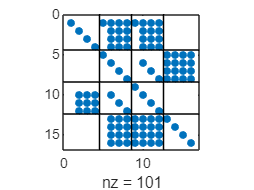


clf
spy(A)
hold on
widths = [N_num+1, M_num+1, M_num+1, K_num+1];
bars = .5 + [widths(1), sum(widths(1:2)), sum(widths(1:3))];
full_line = [0,1+sum(widths)];

plot(bars(1)*[1,1], full_line, 'k') % first vertical
plot(bars(2)*[1,1], full_line, 'k') % second vertical
plot(bars(3)*[1,1], full_line, 'k') % third vertical

plot(full_line, bars(1)*[1,1], 'k') % first horizontal
plot(full_line, bars(2)*[1,1], 'k') % first horizontal
plot(full_line, bars(3)*[1,1], 'k') % first horizontal


A_num = double(subs(A, symbs,nums));
b_num = double(subs(b, symbs,nums));

cond(A_num)

ans = 1.2689e+08

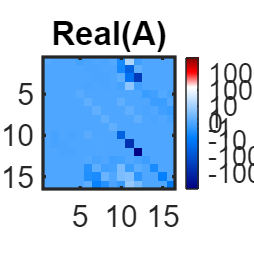

signed_log(real(A_num))
title('Real(A)')

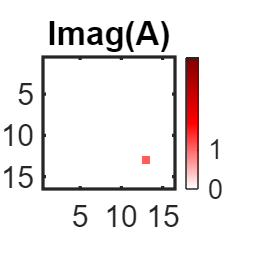


signed_log(imag(A_num))
title('Imag(A)')


x_unscaled = full(A_num\b_num)

x_unscaled =    0.8701 + 0.7071i
   0.5484 - 0.0294i
  -3.9953 + 0.1415i
  56.1169 - 1.9889i
   0.7793 + 0.7119i
   0.0826 - 0.0162i
  -0.0242 + 0.0044i
   0.0218 - 0.0037i
   0.0000 + 0.0000i
   0.0026 - 0.0001i



for maxval = [1e5 5e4]
    rows_to_scale = any(abs(full(A_num))>maxval,2);
    
    A_num(rows_to_scale,:) = A_num(rows_to_scale,:) / 10;
    b_num(rows_to_scale) = b_num(rows_to_scale) / 10;
end


cond(A_num)

ans = 1.2689e+08


x = full(A_num\b_num)

x =    0.8701 + 0.7071i
   0.5484 - 0.0294i
  -3.9953 + 0.1415i
  56.1169 - 1.9889i
   0.7793 + 0.7119i
   0.0826 - 0.0162i
  -0.0242 + 0.0044i
   0.0218 - 0.0037i
   0.0000 + 0.0000i
   0.0026 - 0.0001i


% get potential field
% eq 6
phi_h_n_i1(n) = (C_1n_1(n) * R_1n_1(n) + C_2n_1(n) * R_2n_1(n)) * Z_n_i1(n);
phi_h_m_i2(n) = (C_1m_2(m) * R_1m_2(m) + C_2m_2(m) * R_2m_2(m)) * Z_m_i2(m);

% eq 12
phi_e_k(k) = B_k(k) .* Lambda_k(k) .* Z_k_e(k);

% simplify
phi_h_n_i1(n) = simplify(phi_h_n_i1(n),'IgnoreAnalyticConstraints',true);
phi_h_m_i2(m) = simplify(phi_h_m_i2(m),'IgnoreAnalyticConstraints',true);
phi_e_k(k)    = simplify(phi_e_k(k),   'IgnoreAnalyticConstraints',true);


% sum all N terms
syms N M K real positive integer
syms phi_i1(N) phi_i2(M) phi_e(K) phi_h_i1(N) phi_h_i2(M)
phi_h_i1(N) = symsum(phi_h_n_i1, n, 0, N);
phi_h_i2(M) = symsum(phi_h_m_i2, m, 0, M);
phi_i1(N) = phi_p_i1 + phi_h_i1;
phi_i2(M) = phi_p_i2 + phi_h_i2;
phi_e(K)  = symsum(phi_e_k, k, 0, K);

% subs m_k_const for m_k(n) - note that it might make more sense to start
% with m_k_const in the beginning so this is never necessary
phi_e(K) = subs(phi_e(K), m_k(k), m_k_const);

% vars = symvar(phi_i1)

% matlabFunction(phi_i1,phi_i2,phi_e,'File','generated/phi','Vars',vars)
% this errors due to matlab symsum bug

% matlabFunction of each n term indiviudally due to matlab symsum bug
%vars_n = symvar(phi_h_n_i1)
%matlabFunction(phi_h_n_i1,phi_h_n_i2,phi_e_k,'File','generated/phi_n','Vars',vars_n)
%vars_p = symvar([phi_p_i1 phi_p_i2])
%matlabFunction(phi_p_i1,phi_p_i2,'File','generated/phi_p','Vars',vars_p)

% matlabFunction of entire potential
%syms phi_h_n_i1_fcn([n, a1, a2, d1, d2, h, m0, m_k_const, r, z]) phi_h_n_i2_fcn([n, a1, a2, d1, d2, h, m0, m_k_const, r, z]) ...
%    phi_e_k_fcn([n, a1, a2, d1, d2, h, m0, m_k_const, r, z]) N
%vars_cell = sym2cell(vars_n);
%[phi_h_n_i1_fcn, phi_h_n_i2_fcn, phi_e_k_fcn] = phi_n(vars_cell{:})



% derivatives to geometric variables

% hydro_terms = [mu,lambda];
% J = jacobian(hydro_terms,geom_vars);
% J = J(n) % turn symfun into sym so I can index matrix elements
% spy(J)
% xticklabels({'','a_1','a_2','d_1','d_2','h'})
% yticklabels({'','\mu','\lambda'})

% get symbolic velocity
v_1r = diff(phi_i1,r);
v_1z = diff(phi_i1,z);
v_2r = diff(phi_i2,r);
v_2z = diff(phi_i2,z);
v_er = diff(phi_e,r);
v_ez = diff(phi_e,z);

% get symbolic hydro coeffs
% equation 28 in old 1981 paper
% OC = heaving outer cylinder
% IC = heaving inner cylinder
integrand_OC = subs(r * phi_i2 * v_2z, z, -d2);
integrand_IC = subs(r * phi_i1 * v_1z, z, -d1);
hydro_OC = h^3 * int(integrand_OC,r,a1,a2);
hydro_IC = h^3 * int(integrand_IC,r,0,a1);

if heaving_OC && heaving_IC
    hydro_over_rho(N,M) = hydro_OC(M) + hydro_IC(N);
    hydro_nondim = hydro_over_rho / (pi * a2^3);
elseif heaving_OC
    hydro_over_rho = hydro_OC;
    hydro_nondim = hydro_OC / (pi * a2^3);
elseif heaving_IC
    hydro_over_rho = hydro_IC;
    hydro_nondim = hydro_IC / (pi * a1^3);
else
    error('neither body is setup to move')
end

% plug in numbers
% 
% hndInfDepth = limit(hnd,h,inf)
% matlabFunction(hydro_nondim,'File','generated/hydro_nondim','Vars',symvar(hydro_nondim))
% geom_vars = [a1,a2,d1,d2,h];
% J = jacobian(hydro_nondim,geom_vars)
% matlabFunction(J,'File','generated/derivatives','Vars',symvar(J))
% 
% hydro_nondim = subs(hydro_nondim, sin(sym(pi)*npos),0);
% hydro_nondim = subs(hydro_nondim, cos(sym(pi)*npos), (-1)^npos)
% hydro_nondim = simplify(hydro_nondim)

% mu_IC = real(hydro_nondim_IC);
% mu_OC = real(hydro_nondom_OC);
% lambda_IC = imag(hydro_nondim_IC);
% lambda_OC = imag(hydro_nondim_OC);



spatial_res = 50;
r_vec = linspace(2*a2_num/spatial_res,2*a2_num,spatial_res);
a_eps = 1e-4;
r_vec = sort([r_vec,a1_num*(1-a_eps), a1_num*(1+a_eps), ...
                    a2_num*(1-a_eps), a2_num*(1+a_eps)]);
z_vec = linspace(-h_num,0,spatial_res);
[R,Z] = meshgrid(r_vec,z_vec);

var = {phi_i1,phi_i2,phi_e,phi_p_i1,phi_p_i2,phi_h_i1,phi_h_i2,...
    v_1r,v_1z,v_2r,v_2z,v_er,v_ez,hydro_nondim};
for i = 1:length(var)
    var{i} = subs(var{i}, [symbs N M K], [nums N_num M_num K_num]);
    var{i} = subs(var{i}, [unknowns m_k(1:K_num)], [x.' m_k_num]);
    if i ~= length(var) % don't sub R and Z for hydro_nondim
        var{i} = subs(var{i}, {r,z},{R,Z});
    end
    var{i} = double(var{i});
end
phi_i1_num = var{1};
phi_i2_num = var{2};
phi_e_num = var{3};
phi_p_i1_num = var{4};
phi_p_i2_num = var{5};
phi_h_i1_num = var{6};
phi_h_i2_num = var{7};
v_1_r_num = var{8};
v_1_z_num = var{9};
v_2_r_num = var{10};
v_2_z_num = var{11};
v_e_r_num = var{12};
v_e_z_num = var{13};
hydro_nondim_num = var{14};

g = 9.806;
omega = sqrt(g * m0_num * tanh(m0_num*h_num));
mu_nondim = real(hydro_nondim_num)

mu_nondim = 0.0789

lambda_nondim = imag(hydro_nondim_num) / omega

lambda_nondim = 0.0214


% assemble total phi based on phi in each region
regione = R > a2_num;
region1 = R <= a1_num & Z < -d1_num;
region2 = R > a1_num & R <= a2_num & Z < -d2_num;

phi = NaN(size(R));
phi(region1) = phi_i1_num(region1);
phi(region2) = phi_i2_num(region2);
phi(regione) = phi_e_num(regione);

phiH = NaN(size(R));
phiH(region1) = phi_h_i1_num(region1);
phiH(region2) = phi_h_i2_num(region2);

phiP = NaN(size(R));
phiP(region1) = phi_p_i1_num(region1);
phiP(region2) = phi_p_i2_num(region2);

v_r = NaN(size(R));
v_r(region1) = v_1_r_num(region1);
v_r(region2) = v_2_r_num(region2);
v_r(regione) = v_e_r_num(regione);

v_z = NaN(size(R));
v_z(region1) = v_1_z_num(region1);
v_z(region2) = v_2_z_num(region2);
v_z(regione) = v_e_z_num(regione);

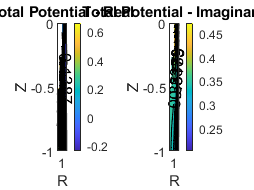

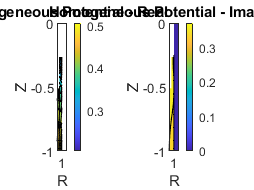

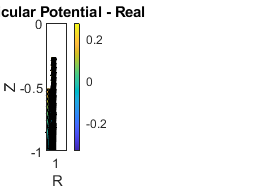

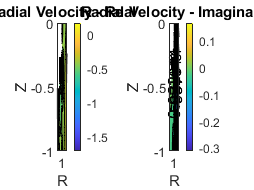

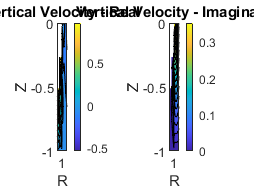

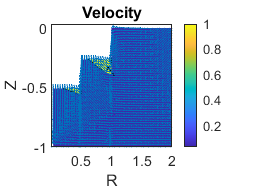

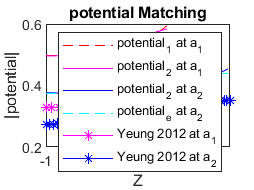

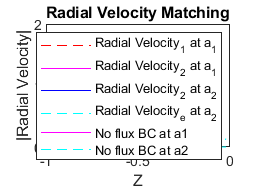


plot_phi = true;
if plot_phi
    region_body = ~region1 & ~region2 & ~regione;
    plot_potential(phi,R,Z,region_body,'Total Potential');
    if heaving_IC && heaving_OC
        heaving = 'both';
    elseif heaving_IC
        heaving = 'inner';
    else
        heaving = 'outer';
    end
    fname = [char(datetime('now','Format','yyyy-MM-dd h-mm a')) ', N,M,K=' num2str(num_harmonics) ...
        ', BC = ' num2str(num) ', heaving = ' heaving];
    folder = ['dev' filesep 'MEEM_figs' filesep fname];
    savefig(folder)
    plot_potential(phiH,R,Z,region_body,'Homogeneous Potential');
    plot_potential(phiP,R,Z,region_body,'Particular Potential');
    plot_potential(v_r,R,Z,region_body,'Radial Velocity')
    plot_potential(v_z,R,Z,region_body,'Vertical Velocity')
    plot_velocity(real(v_r),real(v_z),R,Z);
    z_cutoffs_potential = [-d1_num -d1_num -d2_num -d2_num];
    z_cutoffs_velocity = [-d1_num -d2_num -d2_num 0];
    plot_matching(phi_i1_num,phi_i2_num,phi_e_num,a1_num,a2_num,R,Z,'potential',z_cutoffs_potential)
    plot_validation()
    %plot_matching(phi_h_i1_num,phi_h_i2_num,phi_e_num,a1_num,a2_num,R,Z,'Homogeneous potential',z_cutoffs_potential)
    %plot_matching(phi_p_i1_num,phi_p_i2_num,zeros(size(R)),a1_num,a2_num,R,Z,'Particular potential',z_cutoffs_potential)
    plot_matching(v_1_r_num,v_2_r_num,v_e_r_num,a1_num,a2_num,R,Z,'Radial Velocity',z_cutoffs_velocity)
    plot([-d1_num -d2_num],[0 0],'m','DisplayName','No flux BC at a1')
    plot([-d2_num 0]      ,[0 0],'c--','DisplayName','No flux BC at a2')
    savefig([folder ' VelMatch'])
end

toc

Elapsed time is 134.560190 seconds.


function [] = plot_potential(phi,R,Z,region_body,name)
    figure
    minphi = min(real(phi),[],'all');
    maxphi = max(real(phi),[],'all');

    num_levels = 20;
    if minphi<0
        levels = linspace(minphi,maxphi,num_levels);%[-logspace(log10(-minphi),0,num_levels/2), logspace(0,log10(maxphi),num_levels/2)];
        %levels = sort([levels, 135:145]);
    else
        levels = linspace(minphi,maxphi,num_levels);%[logspace(log10(minphi),log10(maxphi),num_levels)];
    end
    subplot 121
    [c,h_fig] = contourf(R,Z,real(phi),levels);
    clabel(c,h_fig)
    xlabel('R')
    ylabel('Z')
    title([name ' - Real'])
    colorbar;
    %set(gca,'ColorScale','log')
    
    imag_phi = imag(phi);
    if numel(unique(imag_phi)) > 1
        imag_phi(region_body) = NaN;
        subplot 122
        [c,h_fig] = contourf(R,Z,imag_phi,num_levels);
        clabel(c,h_fig)
        xlabel('R')
        ylabel('Z')
        title([name ' - Imaginary'])
        colorbar
    end
end

function plot_matching(phi1,phi2,phie,a1,a2,R,Z,name,z_cutoffs)
    % at R = a1
    idx_a1_minus = R < a1 & R == max(R(R < a1)) & Z < z_cutoffs(1);
    idx_a1_plus  = R > a1 & R == min(R(R > a1)) & Z < z_cutoffs(2);
    phi1_a1 = abs(phi1(idx_a1_minus));
    phi2_a1 = abs(phi2(idx_a1_plus));

    % at R = a2
    idx_a2_minus = R < a2 & R == max(R(R < a2)) & Z < z_cutoffs(3);
    idx_a2_plus  = R > a2 & R == min(R(R > a2)) & Z < z_cutoffs(4);
    phi2_a2 = abs(phi2(idx_a2_minus));
    phie_a2 = abs(phie(idx_a2_plus));

    % plot
    figure
    plot(Z(idx_a1_minus),phi1_a1,'r--', ...
         Z(idx_a1_plus), phi2_a1,'m-')
    hold on
    plot(Z(idx_a2_minus),phi2_a2,'b-', ...
         Z(idx_a2_plus), phie_a2,'c--')
    legend([name '_1 at a_1'],[name '_2 at a_1'],[name '_2 at a_2'],[name '_e at a_2'])
    xlabel('Z')
    ylabel(['|' name '|'])
    title([name ' Matching'])
end

function plot_velocity(v_r,v_z,R,Z)
    v_tot = sqrt(v_r.^2 + v_z.^2);

    num_levels = 10;
    levels = logspace(1,6,num_levels);%logspace(log10(min(v_tot,[],'all')),log10(max(v_tot,[],'all')),num_levels);
    levels = sort([levels, 0:10, 12:2:20]);

    figure
    [c,h_fig] = contourf(R,Z,v_tot,levels);
    clabel(c,h_fig)
    xlabel('R')
    ylabel('Z')
    title('Velocity')
    colorbar
    hold on
    quiver(R,Z,v_r./v_tot,v_z./v_tot)
    %set(gca,'ColorScale','log')
end

function plot_validation()
    a1_potential = readmatrix("dev/MEEM_validation/potential_a1.csv");
    a2_potential = readmatrix("dev/MEEM_validation/potential_a2.csv");
    plot(a1_potential(:,1),a1_potential(:,2),'m-*','DisplayName','Yeung 2012 at a_1')
    plot(a2_potential(:,1),a2_potential(:,2),'b-*','DisplayName','Yeung 2012 at a_2')
end